# Multisine Input Design

**Author:** M. Schoukens - Eindhoven University of Technology

**License and Disclaimer: **BSD 3-Clause "New" or "Revised" License - [link](https://github.com/MaartenSchoukens/SysId-LiveScripts/blob/main/LICENSE)

**Cite As:** M. Schoukens, *SysId LiveScripts - Multisine Input Design*, Eindhoven University of Technology, [https://github.com/MaartenSchoukens/SysId-LiveScripts,](https://github.com/MaartenSchoukens/SysId-LiveScripts,) 2026.

This code is developed and tested in Matlab R2025b Update 3

clear all; % clear workspace
close all; % close all figures
clc; % clear command window

## What is a Multisine?

A multisine is obtained as the sum of multiple harmonically related cosines. Each cosine component has an amplitude and a phase, which can be chosen by the user. 

Due to this the user has complete control over the final amplitude spectrum of the signal. This means that all the energy of the signal can be focused on the frequency range of interest. In contrast, when filtered Gaussian noise or random binary sequences are used to excite the system, there will always be part of the signal energy that is present outside the frequency range of interest.

As has been illustrated in the DFT livescript, when measuring for a finite time $T_0$ only a discrete set of frequencies will result in a periodic signal behavior with periodicity length $T_0$. The lowest frequency that can be excited beyond the $0$ Hz frequency is given by $f_0 = 1/T_0$ (in Hz). Also all integer multiples of $f_0$ will result in periodic signals with periodicity $T_0$. Exciting frequencies that are not an exact multiple of $f_0$ would result in leakage. Furthermore, as we work in a sampled signal setting, frequency components beyond the Nyquist frequency will result in aliasing. As a result, for a multisine of $N$ samples per period, and a sampling frequency $f_s$ (in Hz) or sampling time $T_s = 1/f_s$, resulting in a total period length $T_0 = N/f_s$, or $f_0 = f_s/N$, the discrete-time multisine equation becomes:

$u(k) = \sum_{n = 0}^{N/2-1} A_n \cos(2\pi n f_0 kT_s + \phi_n)$, 

with $k$ being the discrete time index. Hence, by selecting a sampling frequency, and the number of measured samples per period, the user has fixed the frequency grid that can be used for generating periodic multisine excitations. What remains to be selected by the user are the amplitudes $A_n$ and the phases $\phi_n$. The indices $n$ are the so-called frequency bins.

## Implementation - Time- and Frequency Domain Examples

### **Starting Choices **

Before starting the construction of the multisine signal, a number of key choices have to be made. Sometimes these choices are prescribed to you by the measurement setup (e.g. a fixed sampling frequency $f_s$), but often some degree of freedom is available for the user. The main choices to make are: the sampling frequency, the length of one period of the signal in number of samples, which frequencies to excite, and finally the amplitudes and the phases of each excited frequency component. 

Note that instead of choosing the sampling frequency and the length of one period of the signal in number of samples, one could choose other degrees of freedom instead, e.g. choose the frequency resolution $f_0$ and the number of samples per period $N$. In all cases the following relations should hold:

$f_0 = \frac{f_s}{N} = \frac{1}{T_0} = \frac{1}{NT_s}$, 

where $N$ is a natural number and $T_s$ is the sampling interval in seconds.

Let us start by setting these values, and calculating some related values:

N =1000; % number of points per period
fs = 20; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.1; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 4;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

t = 0:Ts:(N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = 0:f0:fs-f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

The ceil and floor operators above are used to ensure that the actual excited frequencies are always in between the provided $f_\mathrm{min}$ and $f_\mathrm{max}$, i.e. $f_\mathrm{min} \leq n_\mathrm{min} f_0$ and $f_\mathrm{max} \geq n_\mathrm{max} f_0$.

In the example implementation we will design a multisine with a constant amplitude over the excited frequencies and random phases:

A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi

### **Time-Domain Implementation**

In time domain, the multisine equation can be implemented in a straightforward way using a for loop over all excited frequencies:

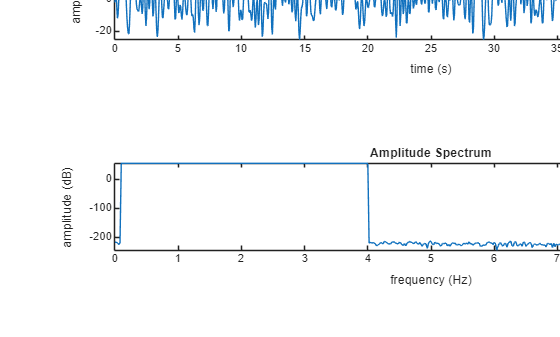

utd = zeros(1,N);
for n=bins
 utd = utd + A(n+1)*cos(2*pi*n*f0*t+phi(n+1));
end
Utd = fft(utd);

figure; tcl = tiledlayout(2,1); title(tcl,'Random Phase Multisine - Time-Domain Implementation')
nexttile; plot(t,utd); xlabel('time (s)'); ylabel('amplitude'); title('Time Domain')
nexttile;  plot(f(1:end/2),db(Utd(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Amplitude Spectrum')

### **Frequency-Domain Implementation**

The frequency-domain implementation first constructs half of the spectrum of the multisine signal. Remember the full spectrum is composed by two parts (the positive and negative frequencies, or, alternatively the part from 0 Hz to the Nyquist frequency on one hand and from Nyquist to the sampling frequency on the other hand which are each others complex conjugate.). Next, by by making use of the complex conjugate nature of the spectrum we have that $U(n) = \bar{U}(N-n)$, and $xy + \bar{x}\,\bar{y} = 2\mathrm{real}(xy)$, which allows to transform the half-sided spectrum in the real-valued time-domain signal by taking the real part of the inverse DFT together with appropriate scaling.

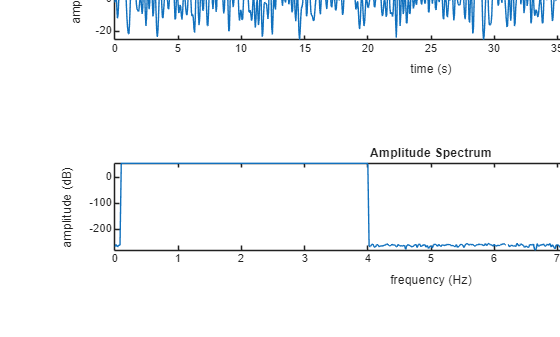

U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
ufd = real(ifft(U))*N;
Ufd = fft(ufd);

figure; tcl = tiledlayout(2,1); title(tcl,'Random Phase Multisine - Freq.-Domain Implementation')
nexttile; plot(t,ufd); xlabel('time (s)'); ylabel('amplitude'); title('Time Domain')
nexttile; plot(f(1:end/2),db(Ufd(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Amplitude Spectrum')

### Scaling and Offset

An additional post-processing step is adding a possibly desired constant offset to the multisine and the scaling of the energy that is present in the multisine:

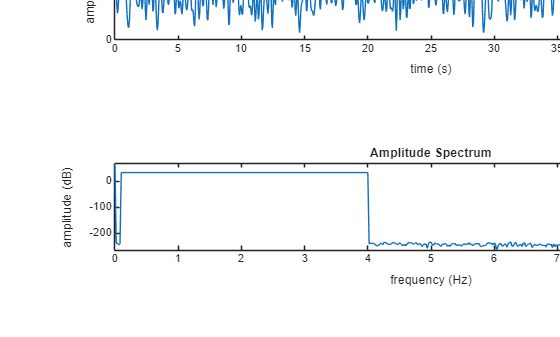

stdu = 1;   % example desired energy in the multisine (without constant offset)
offset = 3; % example desired offset in the multisine

uScaled = stdu*utd/std(utd);
uScaled = uScaled+offset;
UScaled = fft(uScaled);

figure; tcl = tiledlayout(2,1); title(tcl,'Random Phase Multisine - Scaling and Offset')
nexttile; plot(t,uScaled); xlabel('time (s)'); ylabel('amplitude'); title('Time-Domain')
nexttile; plot(f(1:end/2),db(UScaled(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Amplitude Spectrum')

### **Discussion **

The figures show the resulting random phase multisine in time- and frequency domain. The amplitude is plotted in dB in the frequency domain ($\mathrm{dB}(x) = 20 \mathrm{log}_{10}(|x| )$). For a sufficiently large number of excited frequencies, the signal looks rather random in the time domain. In the frequency domain it becomes clear that only the specified frequency range is excited, and that each excited frequency has the same energy. (Note 0 dB = 1 and every step of -20 dB is a factor 10 smaller. Hence amplitudes 200 dB lower than the amplitude of the excited frequencies are$10^{10}$ times smaller then those excited frequencies).

Observe that both implementations result in exactly the same multisine. While the frequency-domain implementation is harder to grasp at first hand, it is a much faster implementation through the use of the fft. After scaling, the shape of the amplitude spectrum is preserved but is scaled. Adding a DC offset adds energy on the 0 Hz frequency bin.

## Choosing the Amplitude and Phase Spectrum

The previous section introduced how to generate a multisine signal, in this section we will study different choices of phases and amplitudes. To start with, we will show the impact of various choices of phases with equal amplitudes for the excited frequencies, next we discuss some scenarios in which specific choices for the amplitude spectrum can be useful.

### Impact of the phase spectrum

#### **Linear Phase**

The phase spectrum of the linear phase multisine is given by

    
$$\phi_n=2 \pi \tau n/N$$
  

where $\tau$ encodes the delay at which the peak in the signal will appear.

A = zeros(1,N/2-1); A(bins+1)=1;  % constant amplitude on the excited frequency bins
Tau=200;  % Delay in samples: translates as the slope of the phase
phi = zeros(1,N/2-1); phi(bins+1) = -bins/N*2*pi*Tau; % linear phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
ulp = real(ifft(U))*N;
ulp = ulp/std(ulp); % scaled to have a standard deviation = 1
Ulp = fft(ulp);

#### **Random Phase**

The phases of each excited frequency component in a random phase multisine are independent and are distributed such that


$$E\left\{e^{i\phi_n} \right\} = 0$$


An example phase distribution that would realize this is a uniform distribution between 0 and $2\pi$: $\phi_n \sim  \mathcal{U}(0,2\pi)$. 

A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
urp = real(ifft(U))*N;
urp = urp/std(urp); % scaled to have a standard deviation = 1
Urp = fft(urp);

#### **Schroeder Phase**

The Schroeder phases for a multisine with $F$ components and $A_n=A$ are given by:

$\phi_n=-n(n-1)\pi/F$.

F = nmax-nmin+1;
A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
% phi = zeros(1,N/2-1); phi(bins+1) = -(bins+1).*(bins).*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
usp = real(ifft(U))*N;
usp = usp/std(usp); % scaled to have a standard deviation = 1
Usp = fft(usp);

Comparing and plotting the results

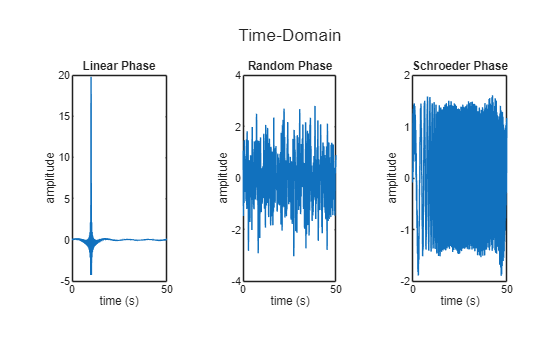

figure; tcl = tiledlayout(1,3); title(tcl,'Time-Domain')
nexttile; plot(t,ulp); xlabel('time (s)'); ylabel('amplitude'); title('Linear Phase'); 
nexttile; plot(t,urp); xlabel('time (s)'); ylabel('amplitude'); title('Random Phase'); 
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder Phase'); 

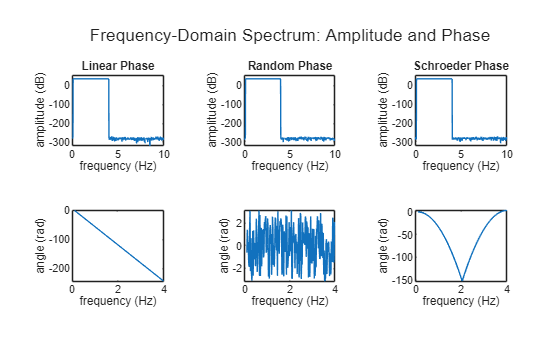


figure; tcl = tiledlayout(2,3); title(tcl,'Frequency-Domain Spectrum: Amplitude and Phase')
nexttile; plot(f(1:end/2),db(Ulp(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Linear Phase'); ylim([-320, max(db(Ulp(1:end/2)))+20]);
nexttile; plot(f(1:end/2),db(Urp(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Random Phase'); ylim([-320, max(db(Ulp(1:end/2)))+20]);
nexttile; plot(f(1:end/2),db(Usp(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Schroeder Phase'); ylim([-320, max(db(Ulp(1:end/2)))+20]);
nexttile; plot(f(bins+1),unwrap(angle(Ulp(bins+1)))); xlabel('frequency (Hz)'); ylabel('angle (rad)')
nexttile; plot(f(bins+1),angle(Urp(bins+1))); xlabel('frequency (Hz)'); ylabel('angle (rad)') % not unwrapped angle as it is random to start with
nexttile; plot(f(bins+1),unwrap(angle(Usp(bins+1)))); xlabel('frequency (Hz)'); ylabel('angle (rad)')

% only the phase of the excited frequencies are plotted as the non-excited
% frequencies have a random phase due to numerical precision.

#### **Discussion**

The different figures illustrate that the multisine is a very versatile input signal. All three signals share the same amplitude spectrum, they excite exactly the same frequencies. As a user, we also have full control over which frequencies are excited, and all the signal energy can be focused on the chosen frequency range. Furthermore, but considering different phase spectra, a very different time domain behavior of the signal is observed. A linear phase results in an impulse like signal which concentrates all its energy over a short duration of time. The random phase multisine looks like (filtered) random Gaussian noise. Finally, the Schroeder phase multisine seems to share some similarity with a swept sine signal.

### Varying Amplitude Spectrum

Imagine a situation in which we would like to measure the dynamics of a system over a broad frequency range, but some frequency regions have worse levels of noise than others. To ensure a similar signal to noise ratio across all frequencies, we can adjust the amplitude spectrum to inject more power on for some frequencies compared to the other excited frequency. The example below shows a piece-wise constant amplitude spectrum implementation. Other shapes of the amplitude spectrum can of course be considered, e.g. linearly increasing or decreasing spectra.

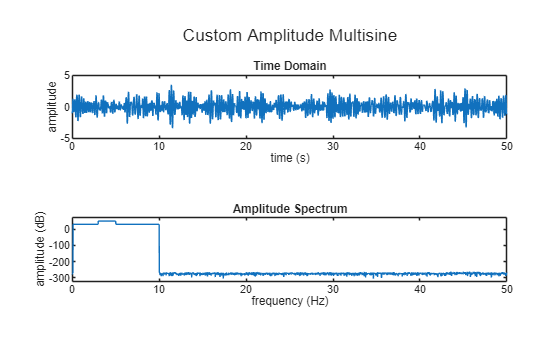

N = 5000; % number of points per period
fs = 100; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.1; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 10;  % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2
fminh = 3; % lowest excited frequency in Hz, high amplitude - should be larger than fmin and smaller than fmaxh
fmaxh = 5; % highest excited frequency in Hz, high amplitude - should be lower than fmax
Ahigh =10; % how much higher is the amplitude of the high amplitude region compared to the regular excited frequencies

t = 0:Ts:(N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = 0:f0:fs-f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

nminh = ceil(fminh/f0);  % the frequency bin of the lowest excited frequency
nmaxh = floor(fmaxh/f0); % the frequency bin of the highest excited frequency
binsh = nminh:nmaxh; % vector containing the excited frequency bins

A = zeros(1,N/2-1); 
A(bins+1)=1; % constant amplitude on the excited frequency bins
A(binsh+1)=Ahigh; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
uva = real(ifft(U))*N;
uva = uva/std(uva); % scaled to have a standard deviation = 1
Uva = fft(uva);

figure; tcl = tiledlayout(2,1); title(tcl,'Custom Amplitude Multisine')
nexttile; plot(t,uva); xlabel('time (s)'); ylabel('amplitude'); title('Time Domain')
nexttile; plot(f(1:end/2),db(Uva(1:end/2))); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); ylim([-320,max(db(Uva(1:end/2)))+20]); title('Amplitude Spectrum')

### Logarithmic Frequency Grid

When designing experiments for systems that exhibit dynamics over multiple frequency decades (e.g. from 0.1 Hz to 1 kHz), it is often desired not to use a uniform frequency spacing. Dynamics around 1 kHz often do not require a 0.01 Hz frequency resolution, while dynamics that are present around 0.1 Hz might need such a resolution. 

If in such a case a uniform frequency distribution and a constant amplitude spectrum would be used, most of the energy of the system would be focused on the high frequencies. This results in poor signal-to-noise ratios in the low frequency region. One way to address this is to use a varying amplitude spectrum across the frequencies as discussed in the previous section, e.g. the amplitude drops with $1/f$. However, this would result in a poor signal to noise ratio in the high frequency regions for e.g. FRF estimation applications as each individual frequency would have significantly less power. 

To address this issue, an approximate logarithmic distribution of the excited frequencies can be used, i.e. the spacing between two consecutive frequencies increases logarithmically when going towards higher frequencies, but assigning the same power to each excited frequency. Of course, when doing so one still needs to ensure that all excited frequencies are an integer multiple of the base frequency $f_0$ to avoid leakage effects.

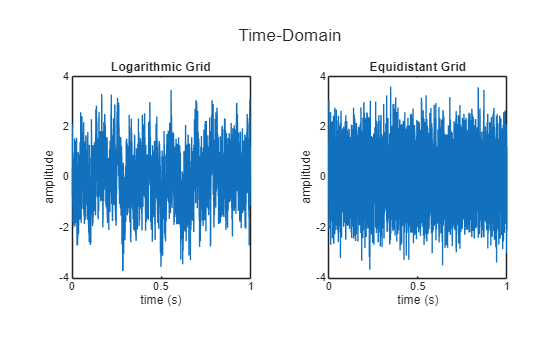

N = 1e4; % number of points per period
fs = 1e4; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = f0;     % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = fs/3;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2
F = 100;    % maximum number of excited frequencies
t = 0:Ts:(N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = 0:f0:fs-f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax;
binslog = round(logspace(log10(nmin),log10(nmax),F)); % logarithmically spaced frequency rounded to closest grid point
binslog = unique(binslog(:).'); % remove frequency bin values that appear multiple times in the vector
% due to this last operation, the total number of excited frequency can be
% lower than the previously defined F.

A = zeros(1,N/2-1); A(binslog+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(binslog+1) = 2*pi*rand(1,length(binslog)); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(binslog+1) = A(binslog+1).*exp(1i*phi(binslog+1));
ulg = real(ifft(U))*N;
ulg = ulg/std(ulg); % scaled to have a standard deviation = 1
Ulg = fft(ulg);

A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,length(bins)); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
ueq = real(ifft(U))*N;
ueq = ueq/std(ueq); % scaled to have a standard deviation = 1
Ueq = fft(ueq);

figure; tcl = tiledlayout(1,2); title(tcl,'Time-Domain')
nexttile; plot(t,ulg); xlabel('time (s)'); ylabel('amplitude'); title('Logarithmic Grid')
nexttile; plot(t,ueq); xlabel('time (s)'); ylabel('amplitude'); title('Equidistant Grid')

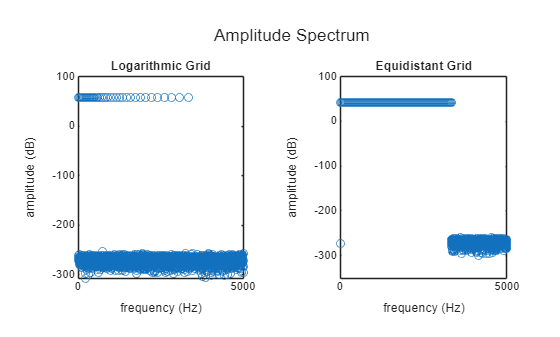

figure; tcl = tiledlayout(1,2); title(tcl,'Amplitude Spectrum')
nexttile; plot(f(1:end/2),db(Ulg(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic Grid'); yl = ylim;
nexttile; plot(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant Grid'); ylim(yl);


Alg = max(abs(Ulg)); disp(['Amplitude of excited frequencies - logarithmic grid: ' num2str(db(Alg)) ' dB'])

Amplitude of excited frequencies - logarithmic grid: 57.9044 dB


Aeq = max(abs(Ueq)); disp(['Amplitude of excited frequencies - equidistant grid: ' num2str(db(Aeq)) ' dB'])

Amplitude of excited frequencies - equidistant grid: 41.7609 dB


The figures display the resulting random phase multisine with a logarithmically spaced and a fully excited (equidistant) frequency grid. Both signals have the same standard deviation (total energy). Since this total energy is spread out over less frequencies in the case of the logarithmic multisine, compared to the equidistant one, each frequency component has a higher amplitude in the logarithmic case. Remember, a difference of 20 dB is a factor 10 difference in amplitude! This can be especially valuable to ensure a sufficient resolution of an FRF estimate across the different frequency decades and at the same time improving the signal to noise ratio at each individual frequency.

## Crest Factor Minimization

The crest factor $\mathrm{crest}_u$ of a signal $u(k)$ is given by

$\mathrm{crest}_u=\frac{\max(|u(k)|)}{\mathrm{rms}(u)}$ , 

with $ k\in\{0,1,\ldots, N-1 \}$ and $\mathrm{rms}(u)=\sqrt{E\left\{u(k)^2\right\}}$ the RMS value of the signal.

For many systems, being able to apply a large energy signal to the system while have a low peak value is important. A large energy means good signal to noise rations, while a small maximum amplitude ensures that the system continues to operate within prescribed safety limits, or within a desired linear regime. Hence, a good input signal is often one that has a small crest factor. The smallest crest factor can be obtained by binary signals $u(k)=\pm 1$ for which $\mathrm{crest}_u=1$.

The above reasoning especially holds for linear systems, for nonlinear systems, more care needs to be taken as the amplitude distribution starts to play a more important role, and the nonlinear system dynamics can be sensitive to particular phase relations that are present across the excited frequencies.

### **Crest Factor of Different Multisines**

For now, let us compare the crest factor for the three considered multisine signals:

crest_ulp = max(abs(ulp))/rms(ulp); disp(['Crest factor - linear phase:    ' num2str(crest_ulp)])

Crest factor - linear phase:    19.799


crest_urp = max(abs(urp))/rms(urp); disp(['Crest factor - random phase:    ' num2str(crest_urp)])

Crest factor - random phase:    3.0372


crest_usp = max(abs(usp))/rms(usp); disp(['Crest factor - Schroeder phase: ' num2str(crest_usp)])

Crest factor - Schroeder phase: 1.8979


As could be expected from the earlier time-domain plots, the linear phase multisine is performing worst in terms of the crest factor. It focuses all its energy in a short impulse and is zero almost everywhere else. The Schroeder phase multisine on the other hand obtains a rather low crest factor, similar to what could be obtained by e.g. a swept sine type of excitation. The random phase multisine has a crest factor in between the previous two, performing similar to what a filtered Gaussian noise excitation would do. To conclude, if one would like to apply as much energy to the system within a certain amplitude range, the Schroeder phase multisine is of particular interest. We will see later in this livescript how we could optimize the crest factor of multisine signals to even better crest factor values.

### **Crest Factor Minimization with a Fixed Amplitude Spectrum**

A simple crest optimization algorithm is given by the iterative time-frequency domain clipping algorithm [Van der Ouderaa et al. 1988]. This algorithm optimizes the crest factor for a multisine with a user-specified amplitude spectrum. Starting from an initial multisine signal, the signal is clipped in the time-domain first: 


$$u_\mathrm{max} = \max(|u^{[i]}(k)|)$$



$$u^{[i]}_c(k) = \eta u_\max \; \forall \; u^{[i]}(k)> \eta u_\max$$



$$u^{[i]}_c(k) = -\eta u_\max \; \forall \; u^{[i]}(k)< -\eta u_\max$$


where $.^{[i]}$ denotes the iteration index, and $\eta$ is a user selected value between 0 and 1 which decides how much of the signal is clipped. An $\eta$-value of 0.95 is a typical choice, lower values will speed up the clipping process but might result in unstable convergence or worse final crest values. This clipping operation will distort the amplitude spectrum of the signal, and also modify the phase spectrum of the signal. Hence, next, the clipped signal is transformed to the frequency domain to restore the user desired amplitude spectrum, while keeping the phase spectrum of the time-domain clipped signal:


$$$U_c^{[i]}(n)$$\,$$=$$\,$$|A^{[i]}_{c,n}| e^{j \phi^{[i]}_{c,n}}= \mathrm{DFT}(u^{[i]}_c(k))$$$



$$U^{[i+1]}(n) = A^{[0]}_n e^{j \phi^{[i]}_{c,n}}$$


where $A^{[0]}_n$ is the desired amplitude spectrum of the multisine signal. Finally, the signal is transformed back to the time domain to restart the iterative loop again


$$u^{[i+1]}(k) = \mathrm{IDFT}(U^{[i+1]}(n))$$


An improved version of this algorithm is published in [Guillaume et al. 1991]. Note that other optimization-based algorithms have been presented in the literature reporting slightly improved performance compared to the algorithm we have discussed here. Nevertheless, the presented clipping-based algorithm is still of high interest due to its simplicity in implementation and its computational efficiency.

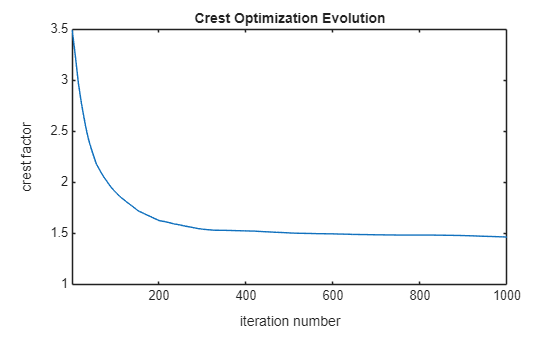

nIter = 1000;
N =1000; % number of points per period
fs = 20; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.1; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 4;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

t = 0:Ts:(N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = 0:f0:fs-f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

% set amplitude spectrum and initial phase spectrum
A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed

U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
uCrest = real(ifft(U))*N;
uCrest = uCrest/std(uCrest);
uInit = uCrest;

crest = zeros(1,nIter+1);
crest(1) = max(abs(uCrest))/rms(uCrest);
for ii=1:nIter
    uOld = uCrest;
    % clip time domain signal
    aClip = 0.95*max(abs(uOld));
    uOld(uOld>aClip) = aClip;
    uOld(uOld<-aClip) = -aClip;

    % take fft and restore amplitude spectrum
    UOld = fft(uOld);
    UCrest = zeros(1,N);
    UCrest(bins+1) = A(bins+1).*exp(1i*angle(UOld(bins+1)));
    % back to time domain
    uCrest = real(ifft(UCrest))*N;
    uCrest = uCrest/std(uCrest);
    % calculate crest factor
    crest(ii+1) = max(abs(uCrest))/rms(uCrest);
end
UInit = fft(uInit);
UCrest = fft(uCrest);

% generate Schroeder phase for comparison
F = length(bins);
% phi = zeros(1,N/2-1); phi(bins+1) = -(bins+1).*(bins).*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
usp = real(ifft(U))*N;
usp = usp/std(usp); % scaled to have a standard deviation = 1
Usp = fft(usp);

% plotting
figure; plot(crest); xlabel('iteration number'); ylabel('crest factor'); title('Crest Optimization Evolution')
xlim([1 length(crest)])

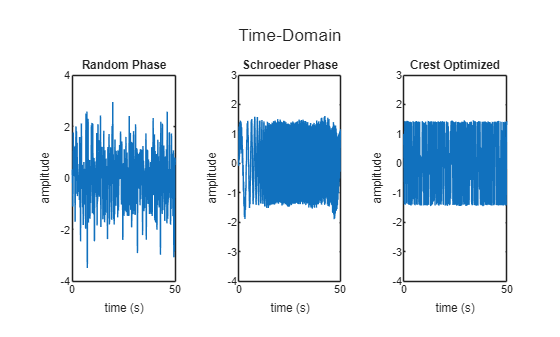


figure; tcl = tiledlayout(1,3); title(tcl,'Time-Domain')
nexttile; plot(t,uInit); xlabel('time (s)'); ylabel('amplitude'); title('Random Phase'); yl = ylim;
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder Phase'); ylim(yl);
nexttile; plot(t,uCrest); xlabel('time (s)'); ylabel('amplitude'); title('Crest Optimized'); ylim(yl);

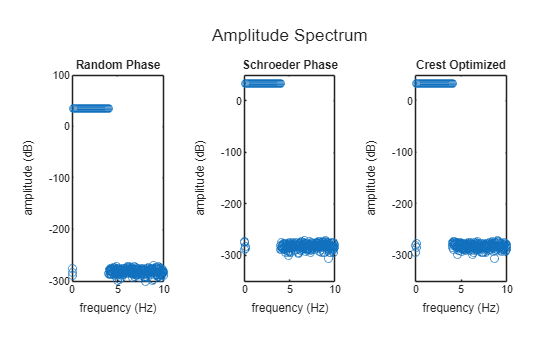

figure; tcl = tiledlayout(1,3); title(tcl,'Amplitude Spectrum')
nexttile; plot(f(1:end/2),db(UInit(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Random Phase'); yl = ylim;
nexttile; plot(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Schroeder Phase'); ylim(yl);
nexttile; plot(f(1:end/2),db(UCrest(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Crest Optimized'); ylim(yl);

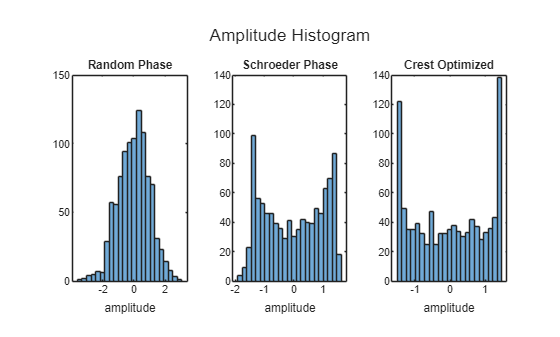

figure; tcl = tiledlayout(1,3); title(tcl,'Amplitude Histogram')
nexttile; histogram(uInit,ceil(sqrt(N/2))); xlabel('amplitude'); title('Random Phase'); yl = ylim;
nexttile; histogram(usp,ceil(sqrt(N/2))); xlabel('amplitude'); title('Schroeder Phase'); ylim(yl);
nexttile; histogram(uCrest,ceil(sqrt(N/2))); xlabel('amplitude'); title('Crest Optimized'); ylim(yl);


crest_uInit = max(abs(uInit))/rms(uInit);    disp(['Crest factor - random phase:    ' num2str(crest_uInit)])

Crest factor - random phase:    3.4926


crest_usp = max(abs(usp))/rms(usp);          disp(['Crest factor - Schroeder phase: ' num2str(crest_usp)])

Crest factor - Schroeder phase: 1.8979


crest_uCrest = max(abs(uCrest))/rms(uCrest); disp(['Crest factor - optimised phase: ' num2str(crest_uCrest)])

Crest factor - optimised phase: 1.4614


From the plotted results it can be observed that the crest optimization iterations converge to a value around 1.5 (for the default script settings), which is slightly lower than what can be achieved by the Schroeder phase multisine signal, and significantly lower than the random phase multisine crest value. All signals in the figures have the same rms value, and the same amplitude spectrum.

Furthermore, it can be seen that the crest optimized multisine tends towards a binary amplitude distribution. While this is beneficial from a crest factor point of view and linear system identification, such an amplitude distribution can be detrimental for nonlinear system identification as having a rich amplitude distribution is paramount there.

## Properties of a Random Phase Multisine

### Periodicity

Earlier in this livescript we have introduced the multisine, and we argued that we selected the frequency grid such that the signal is periodic with a periodicity of $T_0 = 1/f_0 = N/f_s$. So far we always evaluated the multisine signals over one period. Let us know generate a signal over a longer time period, e.g. $PT_0$ seconds:

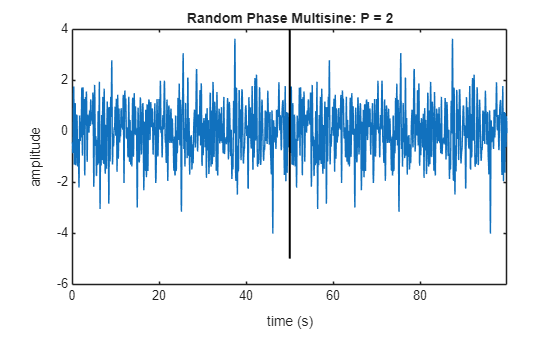

P = 2;
N =1000; % number of points per period
fs = 20; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.1; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 4;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

t = 0:Ts:P*(N-1)*Ts;

A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi
utd = zeros(1,length(t));
for nn=bins
 utd = utd + A(nn+1)*cos(2*pi*nn*f0*t+phi(nn+1));
end
utd = utd/std(utd); % normalize to std = 1

figure; plot(t,utd); xlabel('time (s)'); ylabel('amplitude'); xlim([t(1) t(end)]);
hold on;
yl = ylim;  
for ip = 1:ceil(P)-1
    plot([ip*N*Ts, ip*N*Ts], yl, 'k','linewidth',1.5)
end
title(['Random Phase Multisine: P = ' num2str(P)]) 

As can be seen in the generated figure, when evaluated over a longer time vector, it becomes indeed evident that the generated multisine signal is periodic with a periodicity of $T_0$.

This periodicity can be exploited during estimation to reduce the impact of noise disturbances, to estimate the power spectrum of the noise, or as instrumental variable to reduce the bias of an estimator.

### Amplitude Distribution

A random phase multisine is obtained by summing together sine components of different frequencies, each with a random phase, such that $E\left\{e^{i\phi_n} \right\} = 0$. It can be shown that the amplitude distribution of a random phase multisine tends towards a normal distribution for the number of excited frequencies $F$ tending towards infinity. This is direct consequence from the central limit theorem. However, since a random phase multisine with a finite number of excited frequencies has a finite maximum, its amplitude distribution will be thin-tailed compared to the normal distribution because the latter one is unbounded.

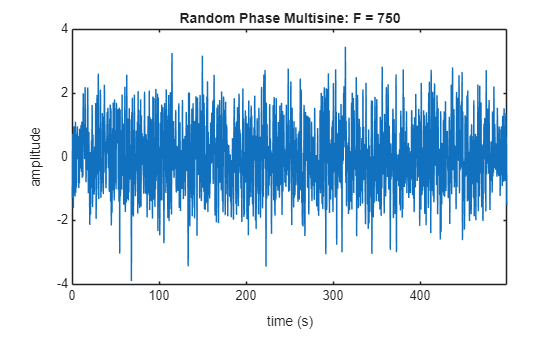

N = 10000; % number of points per period
fs = 20; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
F = 750; % number of excited frequencies

nmin = 1;  % the frequency bin of the lowest excited frequency
nmax = F; % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins
% note: in this example we let F grow by adding higher and higher
% frequencies. We could also let F grow while exciting the same 
% frequency range by making the frequency grid more dense, i.e. let N grow.

t = 0:Ts:(N-1)*Ts;

A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
urp = real(ifft(U))*N;
urp = urp/std(urp); % scaled to have a standard deviation = 1
Urp = fft(urp);

figure;
plot(t,urp); xlabel('time (s)'); ylabel('amplitude'); xlim([t(1) t(end)]);
title(['Random Phase Multisine: F = ' num2str(F)]) 

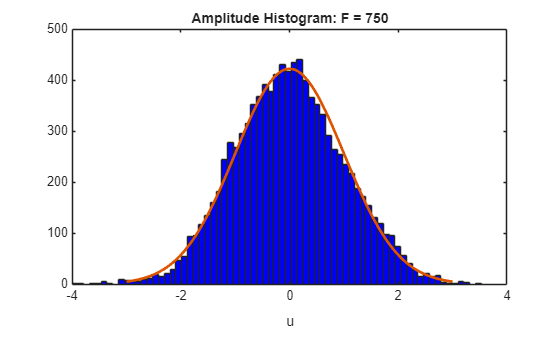

figure
h=histfit(urp,ceil(sqrt(N/2))); h(1).FaceColor = 'b'; xlim([-4,4])
title(['Amplitude Histogram: F = ' num2str(F)]) 
xlabel('u')

In the provided illustration it can be observed that the amplitude distribution of the random phase multisine evolves from a sine distribution ($F=1$) to a normal distribution for $F \rightarrow \infty$

### Stationarity

In this section, we verify if a random phase multisine has stationary stochastic properties over a period. This will be supported by verifying if the correlation $R_{u}(k,\tau)=E[u(k)u(k+\tau)]$ or the variance $\sigma^2(k)=E\{u(k)^2\}$ is time dependent. This correlation and variance will be calculated by using multiple realizations of the random phase multisine $u(k)$ and check the covariance matrix $C(k_1,k_2)=E[u(k_1)u(k_2)]$ and the circular auto-correlation

$R_{c,u}(\tau)=\frac{1}{N}\sum_{k=0}^{N-1}u(k)u(k+\tau)$, for $\tau=0,1,\ldots,N-1$.

Due to the periodicity of the signals, we can replace $u(k+N)$ by $u(k)$.

Remark: The phase $\phi_1$ of the first component in the random phase multisine $u(k)=\sum_{n=n_1}^{n_2}\cos(2\pi\frac{ nkT_s}{N}+\phi_{n})$ is fixed to $\phi_1=0$ to anchor $u(k)$ in time. Without such a constraint, uniformly distributed time shifts could be applied that automatically would result in a signal with stationary properties.

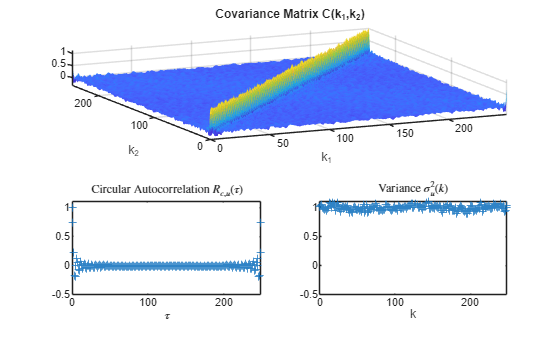

R = 1000; % number of realizations used for covariance and correlation calculation
N = 250; % number of points per period
fs = 20; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
F = 50; % number of excited frequencies

nmin = 1;  % the frequency bin of the lowest excited frequency
nmax = F; % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

t = 0:Ts:(N-1)*Ts;
xConv = zeros(N,R);
C=zeros(N,N);  % initialize covariance matrix
for r=1:R
    A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
    phi = zeros(1,N/2-1); phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi
    phi(nmin+1) = 0; % anchor the multisine
    U = zeros(1,N);
    U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
    urp = real(ifft(U))*N;
    urp = urp/std(urp); % scaled to have a standard deviation = 1

    xrp=[urp urp]; % periodic extension for the circular convolution calculation
    % convolution
    for k=0:N-1
        xConv(k+1,r)=sum(xrp(1:N).*xrp((1:N)+k))/N;
    end
    C=C+urp'*urp; % covariance calculation
end
C=C/R; % normalize covariance with number of realizations
xConvMean=mean(xConv,2);

%% plotting
figure(2)
subplot(2,2,3)
plot(0:N-1,xConvMean,'+')
axis([0 N-1 -0.5 1.1])
xlabel('$\tau$','interpreter','latex')
title('Circular Autocorrelation $R_{c,u}(\tau)$','interpreter','latex')

subplot(2,2,4)
plot(0:N-1,diag(C),'+')
axis([0 N-1 -0.5 1.1])
xlabel('k')
title('Variance $\sigma^2_u(k)$','interpreter','latex')

subplot(2,1,1)
surf(0:N-1,0:N-1,C,'EdgeColor','none')
view([-25 60]); xlim([0 N-1]); ylim([0 N-1])
title('Covariance Matrix C(k_1,k_2)')
xlabel('k_1')
ylabel('k_2')

A random phase multisine with a fixed phase for the first frequency has in general a nonstationary behavior. The expected values depend on the time index $k$ where the signals are evaluated. However, for a growing number of excited frequencies, this dependency decays towards zero. Asymptotically for $F \rightarrow \infty$, we end up with a stationary signal.

## Generating Multisines using the Matlab System Identification Toolbox

The Matlab System Identification toolbox can import arbitrary measurement data, including data generated using multisine input signals. Furthermore, the `idinput` matlab command can generate, among others, random phase multisine input signals (referred to as sum-of-sine signals). A short example is included below.

The full documentation can be found on: [https://nl.mathworks.com/help/ident/ref/idinput.html#d126e84775](https://nl.mathworks.com/help/ident/ref/idinput.html#d126e84775)

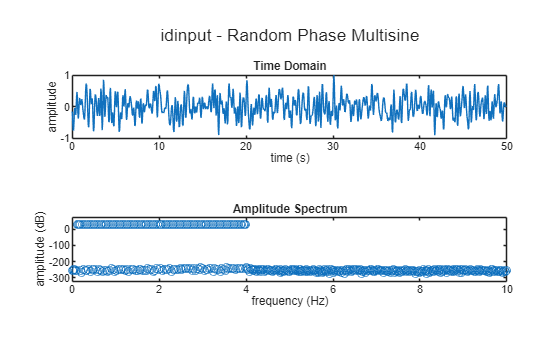

N = 1000; % number of samples per period
P = 1; % number of periods
F = 100; % number excited frequencies
fs = 20;
f0 = fs/N;
fmin = 0.1; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 4;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2
t = 0:Ts:P*(N-1)*Ts;
f = 0:f0:fs-f0;

Range = [-1 1]; % the signal time-domain amplitude will be normalized to stay within this range
Band = [2*fmin/fs 2*fmax/fs]; % F frequencies will be excited equidistantly spread over this range 0=0Hz, 1=fs/2 (Nyquist).
SineData = [F,1,1]; % other options are available for which we refer to the idinput function documentation

[u,freq] = idinput([N 1 P],'sine',Band,Range,SineData); % this function requires the Matlab System Identification Toolbox
U = fft(u(1:N)); % fft of one period only

figure; tcl = tiledlayout(2,1); title(tcl,'idinput - Random Phase Multisine')
nexttile; plot(t,u); xlabel('time (s)'); ylabel('amplitude'); title('Time Domain')
nexttile; plot(f(1:end/2),db(U(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); ylim([-320,max(db(Uva(1:end/2)))+20]); title('Amplitude Spectrum')

Observe that the generated multisine does not excite all the frequencies within the specified frequency band. This is due to the fact that, in this case, we also specify the number of frequencies $F$ we want to excite. Hence, the `idinput` function will spread $F$ frequencies approximately equidistant over the frequency grid within the specified frequency range of excitation. Furthermore, the multisine signal is normalized to have time-domain amplitude between the specified `Range`, and the mean value is set to the mean of this `Range`.

## Generating and Importing Multisines in Simulink

    To be completed.

## Further Reading and References

- R. Pintelon and J. Schoukens, *System Identification: A Frequency Domain Approach*, 2nd Edition, Wiley-IEEE Press, 2012.

- J. Schoukens, R. Pintelon and Y. Rolain, *Mastering System Identification in 100 Exercises*, Wiley-IEEE Press, 2012.

- E. Van der Ouderaa, J. Schoukens, J. Renneboog, *Peak factor minimization using a time-frequency domain swapping algorithm*, IEEE Transactions on Instrumentation and Measurement, 37 (1), pp. 145-147, 1988.

- P. Guillaume, J. Schoukens, R. Pintelon and I. Kollar, *Crest-factor minimization using nonlinear Chebyshev approximation methods*, IEEE Transactions on Instrumentation and Measurement, 40 (6), pp. 982-989, 1991.

- E. Geerardyn, Y. Rolain and J. Schoukens, *Design of Quasi-Logarithmic Multisine Excitations for Robust Broad Frequency Band Measurements*, IEEE Transactions on Instrumentation and Measurement, 62 (5), pp. 1364-1372, 2013.